clear all
syms a_0 a_1 a_2 a_3 b_0 b_1 c_0 c_1 c_2 c_3
syms q_p q_k v
syms t_a t_c t_k t_b
syms d_qk d_qp

a_0 = q_p

$$a\_0 = q_{p}$$

t_c = t_k-t_b;

A = a_0 - q_p

$$A = 0$$


B = a_1 - d_qp

$$B = a_{1}-d_{\mathrm{qp}}$$


C = a_0 + a_1*t_a + a_2*(t_a)^2 + a_3*(t_a)^3 - b_0 - b_1*t_a

$$C = q_{p}-b_{0}+a_{1}\,t_{a}-b_{1}\,t_{a}+a_{2}\,{t_{a}}^{2}+a_{3}\,{t_{a}}^{3}$$


D = a_1 + 2*a_2*t_a + 3*a_3*(t_a)^2 - b_1

$$D = 3\,a_{3}\,{t_{a}}^{2}+2\,a_{2}\,t_{a}+a_{1}-b_{1}$$


E = a_1 + 2*a_2*t_a + 3*a_3*(t_a)^2 - c_1 - 2*c_2*t_c - 3*c_3*(t_c)^2

$$E = a_{1}-c_{1}+2\,a_{2}\,t_{a}+2\,c_{2}\,\left(t_{b}-t_{k}\right)+3\,a_{3}\,{t_{a}}^{2}-3\,c_{3}\,{\left(t_{b}-t_{k}\right)}^{2}$$


F = b_1 - v

$$F = b_{1}-v$$


G = b_0 + b_1*t_c - c_0 - c_1*t_c - c_2*(t_c)^2 - c_3*(t_c)^3

$$G = b_{0}-c_{0}-b_{1}\,\left(t_{b}-t_{k}\right)+c_{1}\,\left(t_{b}-t_{k}\right)-c_{2}\,{\left(t_{b}-t_{k}\right)}^{2}+c_{3}\,{\left(t_{b}-t_{k}\right)}^{3}$$


H = b_1 - c_1 - 2*c_2*t_c - 3*c_3*(t_c)^2

$$H = b_{1}-c_{1}+2\,c_{2}\,\left(t_{b}-t_{k}\right)-3\,c_{3}\,{\left(t_{b}-t_{k}\right)}^{2}$$


I = c_0 + c_1*t_k + c_2*(t_k)^2 + c_3*(t_k)^3 -q_k

$$I = c_{3}\,{t_{k}}^{3}+c_{2}\,{t_{k}}^{2}+c_{1}\,t_{k}+c_{0}-q_{k}$$


J = c_1 + 2*c_2*t_k + 3*c_3*(t_k)^2 - d_qk

$$J = 3\,c_{3}\,{t_{k}}^{2}+2\,c_{2}\,t_{k}+c_{1}-d_{\mathrm{qk}}$$


[Z] = solve(A==0, B==0, C==0, D==0, E==0, F==0, G==0, H==0, I==0, J==0 ,a_0, a_1, a_2, a_3, b_0, b_1, c_0, c_1, c_2, c_3)

Z = struct with fields:
    q_p: q_k - (d_qp*t_a)/2 - (d_qk*t_b)/2 + (t_a*v)/2 + (t_b*v)/2 - t_k*v
    a_1: d_qp
    a_2: -(d_qp - v)/(2*t_a)
    a_3: 0
    b_0: q_k - (d_qk*t_b)/2 + (t_b*v)/2 - t_k*v
    b_1: v
    c_0: (2*q_k*t_b + d_qk*t_k^2 - t_k^2*v - 2*d_qk*t_b*t_k)/(2*t_b)
    c_1: (d_qk*t_b - d_qk*t_k + t_k*v)/t_b
    c_2: (d_qk - v)/(2*t_b)
    c_3: 0


temp = 10×1 cell array
    {[q_k - (d_qp*t_a)/2 - (d_qk*t_b)/2 + (t_a*v)/2 + (t_b*v)/2 - t_k*v]}
    {[d_qp                                                             ]}
    {[-(d_qp - v)/(2*t_a)                                              ]}
    {[0                                                                ]}
    {[q_k - (d_qk*t_b)/2 + (t_b*v)/2 - t_k*v                           ]}
    {[v                                                                ]}
    {[(2*q_k*t_b + d_qk*t_k^2 - t_k^2*v - 2*d_qk*t_b*t_k)/(2*t_b)      ]}
    {[(d_qk*t_b - d_qk*t_k + t_k*v)/t_b                                ]}
    {[(d_qk - v)/(2*t_b)                                               ]}
    {[0                                                                ]}


$$val = \left(\begin{array}{c} -16\\ 20\\ -\frac{5}{4}\\ 0\\ 4\\ 10\\ -20\\ 18\\ -\frac{2}{3}\\ 0 \end{array}\right)$$

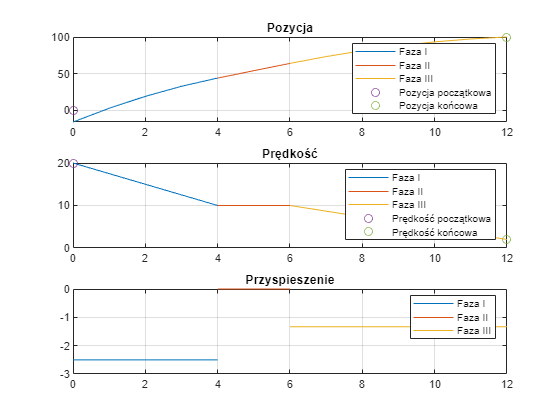

solved = Z;
q_p_in = 0;
dq_p_in = 20;
q_k_in = 100;
dq_k_in = 2;
Tk_in = 12;
Ta_in = 4;
Tb_in = 6;
dt_in = 1;
V_in = 10;
out = Trajectory_Generation(solved, q_p_in, dq_p_in, q_k_in, dq_k_in, Tk_in, Ta_in, Tb_in, dt_in, V_in);

temp = 10×1 cell array
    {[q_k - (d_qp*t_a)/2 - (d_qk*t_b)/2 + (t_a*v)/2 + (t_b*v)/2 - t_k*v]}
    {[d_qp                                                             ]}
    {[-(d_qp - v)/(2*t_a)                                              ]}
    {[0                                                                ]}
    {[q_k - (d_qk*t_b)/2 + (t_b*v)/2 - t_k*v                           ]}
    {[v                                                                ]}
    {[(2*q_k*t_b + d_qk*t_k^2 - t_k^2*v - 2*d_qk*t_b*t_k)/(2*t_b)      ]}
    {[(d_qk*t_b - d_qk*t_k + t_k*v)/t_b                                ]}
    {[(d_qk - v)/(2*t_b)                                               ]}
    {[0                                                                ]}


$$val = \left(\begin{array}{c} 114\\ 2\\ 1\\ 0\\ 98\\ 10\\ 80\\ 16\\ -\frac{1}{2}\\ 0 \end{array}\right)$$

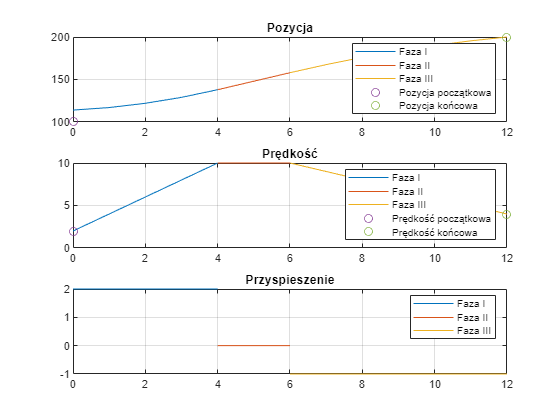

solved = Z;
q_p_in = 100;
dq_p_in = 2;
q_k_in = 200;
dq_k_in = 4;
Tk_in = 12;
Ta_in = 4;
Tb_in = 6;
dt_in = 1;
V_in = 10;
out_1 = Trajectory_Generation(solved, q_p_in, dq_p_in, q_k_in, dq_k_in, Tk_in, Ta_in, Tb_in, dt_in, V_in);

function [q,dq,ddq] = Trajectory_Generation(solved, q_p_in,dq_p_in,q_k_in,dq_k_in,Tk_in,Ta_in,Tb_in,dt_in,V_in)
    syms q_p q_k v
    syms t_a t_c t_k t_b
    syms d_qk d_qp
    temp = struct2cell(solved) %NA LABY
    val = subs(temp,{q_p, d_qp, q_k, d_qk, t_k, t_a, t_b, v},{q_p_in dq_p_in q_k_in dq_k_in Tk_in Ta_in Tb_in V_in}) %NA LABY
    %val = subs(solved,{q_p, d_qp, q_k, d_qk, t_k, t_a, t_b, v},{q_p_in dq_p_in q_k_in dq_k_in Tk_in Ta_in Tb_in V_in});
    t1 = 0:dt_in:Ta_in;
    q_1 = val(1) + val(2) * t1 + val(3) * (t1).^2 + val(4) * (t1).^3;
    d_q1 = val(2) + 2*val(3)*t1 + 3*val(4) * (t1).^2;
    dd_q1 = 2*val(3) + 6*val(4)*t1;
    
    t2 = Ta_in:dt_in:Tb_in;
    q_2 = val(5) + val(6) * t2;
    d_q2 = val(6) + zeros(1, length(t2));
    dd_q2 = zeros(1, length(t2));
    
    t3 = Tb_in:dt_in:Tk_in;
    q_3 = val(7) + val(8) * t3 + val(9) * (t3).^2 + val(10) * (t3).^3;
    d_q3 = val(8) + 2*val(9)*t3 + 3*val(10) * (t3).^2;
    dd_q3 = 2*val(9) + 6*val(10)*t3;

    t = [0:dt_in:Tk_in];
    q = [q_1, q_2, q_3];
    dq = [d_q1, d_q2, d_q3];
    ddq = [dd_q1, dd_q2, dd_q3];

    figure;
    subplot(3, 1, 1);
    plot(t1, q_1, t2, q_2, t3, q_3, t1(1), q_p_in, 'o', Tk_in, q_k_in, 'o')
    legend('Faza I', 'Faza II', 'Faza III', 'Pozycja początkowa', 'Pozycja końcowa')
    title('Pozycja')
    grid on
    axis auto

    subplot(3, 1, 2);
    plot(t1, d_q1, t2, d_q2, t3, d_q3, t1(1), dq_p_in, 'o', Tk_in, dq_k_in, 'o')
    legend('Faza I', 'Faza II', 'Faza III', 'Prędkość początkowa', 'Prędkość końcowa')
    title('Prędkość')
    grid on
    axis auto

    subplot(3, 1, 3);
    plot(t1, dd_q1, t2, dd_q2, t3, dd_q3)
    legend('Faza I', 'Faza II', 'Faza III')
    title('Przyspieszenie')
    grid on
    axis auto
end




